# Model and Control Autonomous Vehicle in Offroad Scenario

This example shows how to integrate planners and controllers designed in the four preceding examples using Simulink® and Stateflow®. The previous four examples showed how to create maps from terrain data and create planners to enable a haul truck to navigate between points of interest in those maps.

See these examples for more information about these steps:

- [Create Route Planner for Offroad Navigation Using Digital Elevation Data](matlab:open('./CreateRoutePlannerUsingDigitalElevationData.mlx'))

- [Create Terrain-Aware Global Planners for Offroad Navigation](matlab:open('./CreateTerrainAwareGlobalPlanners.mlx'))

- [Navigate Global Path through Offroad Terrain Using Local Planner](matlab:open('./CreateLocalPlannerToNavigateGlobalPath.mlx'))

- [Create Path Following MPC Controller](matlab:open('/CreatePathFollowingMPCController'))

## Creating Autonomous Planning Stack

### Open the Model

Begin by loading the maps created and vehicle parameters chosen in previous examples. 

exampleHelperCreateBehaviorModelInputs
exampleHelperPrepMPCInputs

Define a start location, goal location, and initial translation and rotation for the haul truck. The start location and goal locations are given in 2D space as [x, y, theta]. The initial translation (location) of the truck is given in 3D space as [x, y, z], adjusting for the map center and terrain elevation. The initial rotation of the truck is also given in 3D space as [yaw, pitch, roll].

startPose = [267.5 441.5 -pi/2]; % [x,y,theta]
goalPose  = [479.5  210.5 pi/2]; % [x,y,theta]
initialTranslationTruck = [(startPose(1:2)-mapSize/2) mapHeight.getMapData(startPose(1:2))-zOffset+8];
initialRotationTruck = [startPose(3) 0 0];

Open the top-level Simulink model.

model = 'IntegratedBehaviorModule';
open_system(model);

The model has 4 primary components:

- **Operating Mode Logic. **This component is our scheduler. It controls which planning algorithms are active, based on user input and the vehicle's current location. 

- **Global Planning**. This component includes the algorithms where the vehicle determines an overall path to get from the `startPose` to the `goalPose`. It includes the Route Planner developed in the example "[Create Route Planner for Offroad Navigation Using Digital Elevation Data](matlab:open('./CreateRoutePlannerUsingDigitalElevationData.mlx'))", and the Terrain-Aware Planners developed in the example "[Create Terrain-Aware Global Planners for Offroad Navigation](matlab:open('./CreateTerrainAwareGlobalPlanners.mlx'))". The Route Planner plans along the road network. The Terrain-Aware Planners plan in free space outside the road network. 

- **Local Planning and Following**. This component includes the algorithms that help the vehicle navigate along the global paths planned in the previous component. It includes the Local Planner developed in the example "[Navigate Global Path through Offroad Terrain Using Local Planner](matlab:open('./CreateLocalPlannerToNavigateGlobalPath.mlx'))", and the MPC-based Path Follower developed in the example "[Create Path Following MPC Controller](matlab:open('/CreatePathFollowingMPCController'))". 

- **Platform and Environment Model**. This component includes the physics model for the truck, as well as information about the environment. For simple, quick simulations, this component uses a bicycle kinematics model. For higher fidelity simulations, this component connects to Unreal. You can choose whether to use the simple model or the Unreal simulation in the code below.

Create a figure for visualizing the map, planned paths, and the vehicle progress throughout the simulation. Note that the simulation updates the figure as the simulation runs.

f = figure; 
f.Visible = "on";
binMap = binaryOccupancyMap(~imSlope);

### Choose Simulation Options

Before running the simulation, we can configure additional options specific to the upcoming run. Default parameters for these values were previously set in the `exampleHelperCreateBehaviorModelInputs` script, but can be changed using the controls below.

Use the drop-down below to choose a platform and environment model for the truck.

- **Simple** will use a Bicycle Kinematics Model block to represent the mining truck. The truck location during simulation will be updated on the figure created in the previous section.

- **Unreal** will use the Simulation 3D Physics Dump Truck block to represent the mining truck. In addition to seeing the truck location on the figure created in the previous section during simulation, you will also be able to visualize the truck's motion in Unreal. 

vssPhysModel = "Simple";

% If using Unreal, ensure access to the open pit mine scene. 
if vssPhysModel == "Unreal"
    sceneName = "Offroad pit mining scene";
    mapFile = fullfile(userpath,'sim3d_project',matlabRelease.Release,'WindowsNoEditor\AutoVrtlEnv\Content\Paks\Maps.xlsx');
    if ~exist(mapFile,"file") || all(~contains(string(readtable(mapFile).MapName),sceneName))
        sim3d.maps.Map.download(sceneName);
    end
    plantVariant = '/PlatformAndEnv/Platform Model/Unreal (3D)/Simulation 3D Scene Configuration';
    set_param(model,"SimulationCommand","stop");
    set_param([model plantVariant],'ProjectFormat','Default Scenes');
    set_param([model plantVariant],"SceneDesc","Offroad pit mining scene");
end

Use the drop-down below to choose a communication protocol for this simulation run.

- **Simulink Signals **will have all the individual components of the navigation stack communicate with each other through the top-level Simulink model.

- An alternative to this option would be to have the individual components of the navigation stack communicate through middleware, such as ROS.

vssCommProtocol = "SLSignals";

Use the sliders below to change any of the vehicle's local planner parameters.

% Vehicle minimum turning radius (m)
tuneableTEBParamsCpp.MinTurningRadius = 17.2;

% Maximum allowed linear velocity (m/s)
tuneableTEBParamsCpp.MaxVelocity(1) =16;

% Maximum allowed angular velocity (rad/s)
tuneableTEBParamsCpp.MaxVelocity(2) =0.93;

% Maximum allowed linear reverse velocity (m/s)
tuneableTEBParamsCpp.MaxReverseVelocity =8;

% Maximum allowed linear acceleration (m/s^2)
tuneableTEBParamsCpp.MaxAcceleration(1) =0.6;

% Maximum allowed angular acceleration (rad/s^2)
tuneableTEBParamsCpp.MaxAcceleration(2) =0.1;

% Safety distance between vehicle and obstacles (m)
tuneableTEBParamsCpp.ObstacleSafetyMargin = 1;

% Amount of time the controller generates velocity commands for
tuneableTEBParamsCpp.LookaheadTime = 6;

Use the sliders below to change any of the weights the local planner's cost function optimization uses. 

% Time weight: the higher the level, the shorter the travel time
tuneableTEBParamsCpp.CostWeights_T.Time = 100;

% Smoothness weight: the higher the weight, the smoother the path
tuneableTEBParamsCpp.CostWeights_T.Smoothness = 500;

% Obstacle weight: the higher the weight, the more obstacle avoidance is prioritized
tuneableTEBParamsCpp.CostWeights_T.Obstacle =10;

Use the drop-down below to choose a map visualization for the simulation.

- **Signed Distance Field** maps show distances to obstacles. Points on the map will return positive values if they lie outside an occupied region of space. Points on the map will return negative values if they lie inside an occupied region of space.

- **Binary Occupancy Map** shows whether a region is occupied (in black) or empty (in white). 

- **Occupancy Map** shows the probability of whether a region is occupied, ranging from definitely (in black) to possibly (in gray) to definitely not (white).  

maptype = 'Bin';
set_param([model '/Visualization and Server Functions/Map Viz'],"MapType",maptype);

You can also change parameters like plotting colors, widths, and styles on the system object blocks in the "Visualization and Server Functions" subsystem. By default, the map will use the binary occupancy map. The road network (graph) is plotted in dark blue, the global path is plotted in orange, the local planner output is plotted in light blue, and the MPC path follower output is plotted in pink.

### Simulating the Autonomous Vehicle

Now that the simulation parameters have been set, you can run the model by clicking on the "Run" button on the "Simulation" tab of the Simulink Toolstrip.

After starting the model, the haul truck will stay in the "WaitingForTask" state until you click the "Begin Navigation" button in the model.  

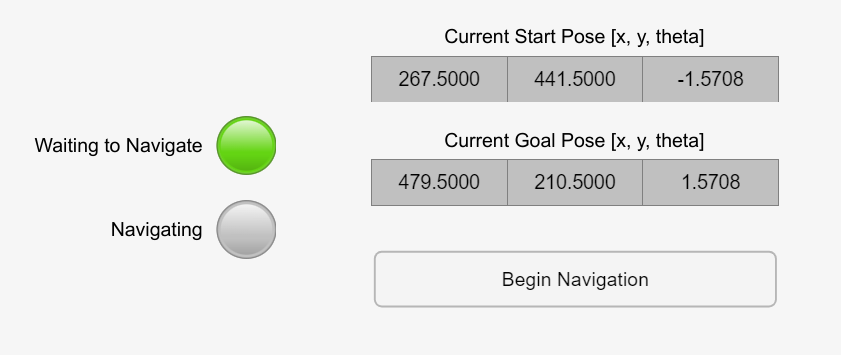

You can also run the simulation programmatically by running the code below.

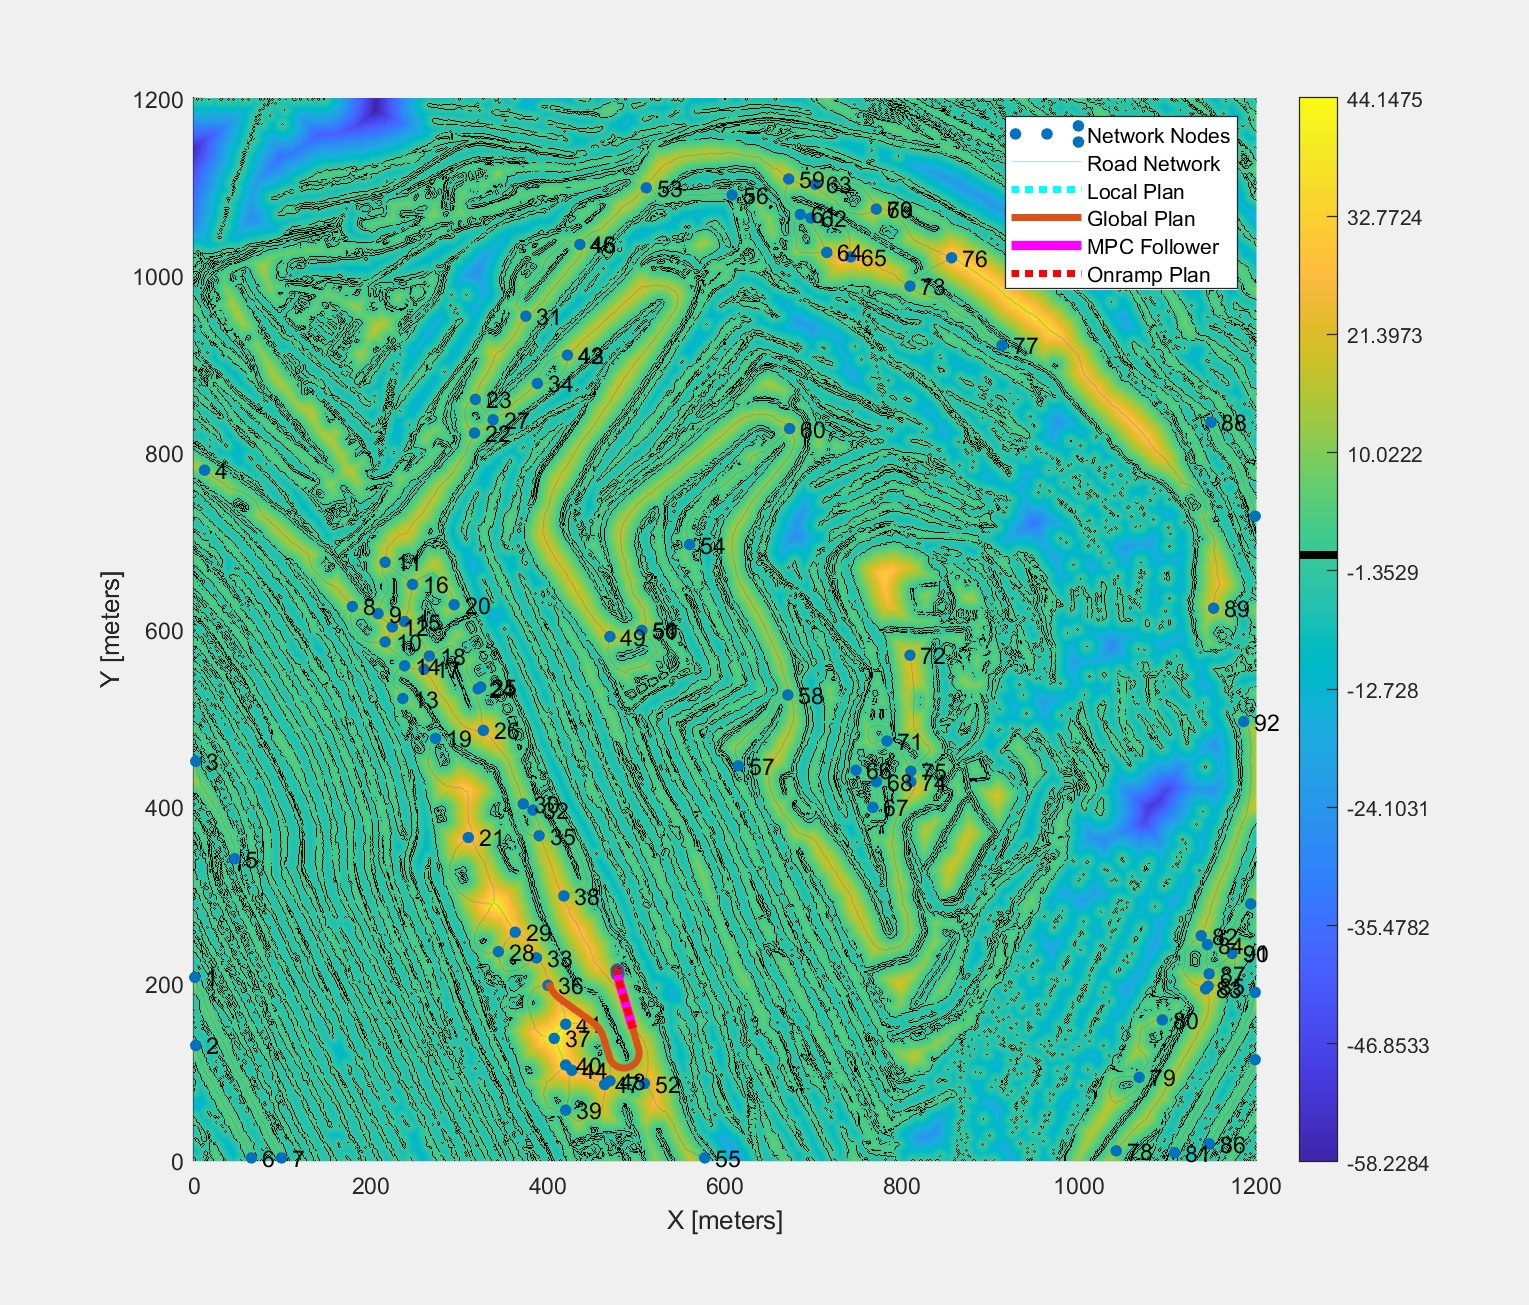

% Start the simulation. 
sm = simulation(model);
start(sm);

% Update the goal location to start navigating.
goalBlockPath = [model '/TaskControllerIn/Simulink Signals/Confirm New Goal/newGoalBlock'];
sm = setBlockParameter(sm, goalBlockPath,"Value","goalPose");
pause(1);

% If the goal has been reached, end the simulation. 
pause(sm);
while get(sm.SimulationOutput.logsout,"TaskControllerMode").Values.Data(end) ~= "WaitingForTask"
    t = sm.Time;
    step(sm,"PauseTime",t+10); % Checks currently active state every 10 seconds of simulation time.
end
stop(sm);



## Results and Discussion

This example demonstrated how to integrate different planning subsystems together to create a navigation stack for an offroad autonomous vehicle. The individual algorithms of the navigation stack were developed and tested incrementally in MATLAB code, then brought into Simulink for system-level simulation. 

For further information on the states in the Stateflow chart and which parts of the model they trigger, see the following table. The table also shows which of the previous examples align with each operational state.

*Copyright 2023-2024 The MathWorks, Inc.*